# L02: Data and Data visualization: Sleep Hours

% sleep_hours_last_night = rand(10,1);
sleep_hours_last_night = [7 5.5 9 5 5 7 8 7 8 10 6 7 6 5];
% sleep_average = rand(10,1);
sleep_average = [6 6.5 7 7 6 8 7 8 10 9 7.5 9 8 8];

subplot(1,2,1); 
histogram(sleep_hours_last_night, 5);
set(gca, 'fontsize', 20, 'tickdir', 'out', 'ticklength', [.02 .02], ...
    'box', 'off', 'linewidth', 1.5);
set(gcf, 'color', 'w', 'position', [1 1043 759 302]);
ylabel('Frequency');
xlabel('Sleep hours last night');

fprintf('\nMean sleep hours last night is %2.3f, and its standard deviation is %2.3f.\n', ...
    mean(sleep_hours_last_night), std(sleep_hours_last_night));


Mean sleep hours last night is 6.821, and its standard deviation is 1.539.


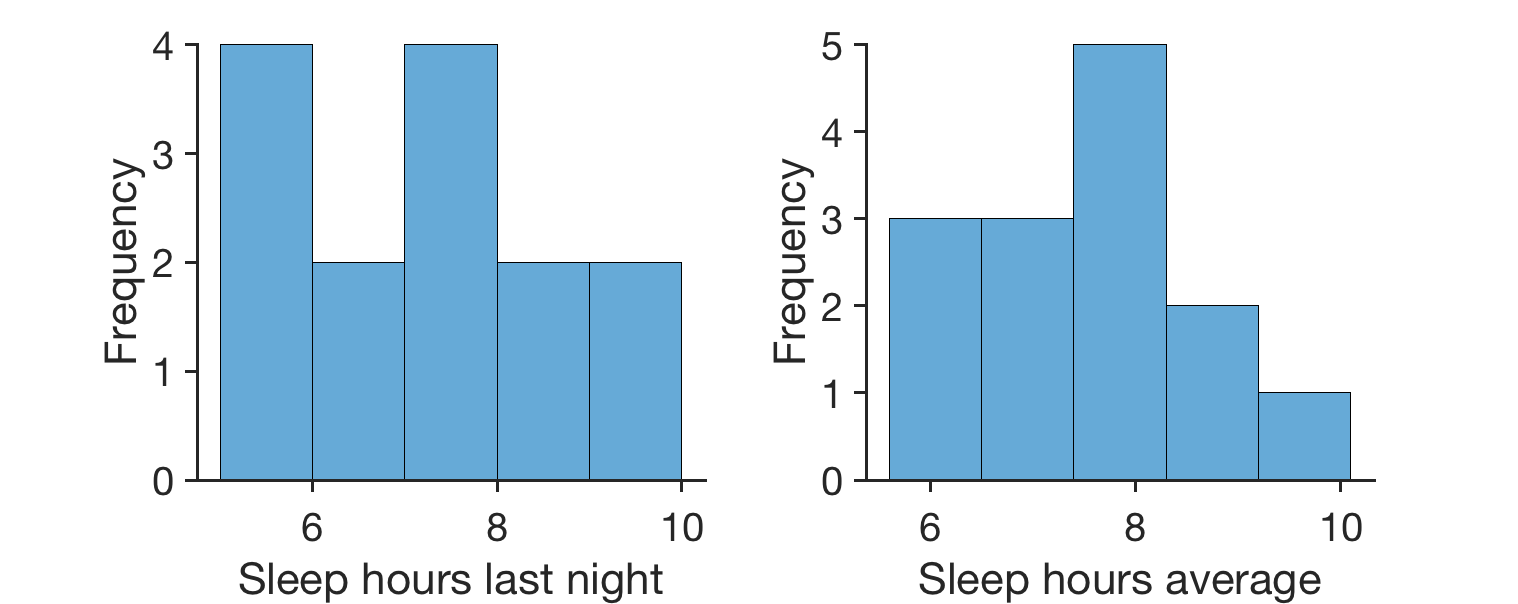


subplot(1,2,2); 
histogram(sleep_average, 5);
set(gca, 'fontsize', 20, 'tickdir', 'out', 'ticklength', [.02 .02], ...
    'box', 'off', 'linewidth', 1.5);
ylabel('Frequency');
xlabel('Sleep hours average');


fprintf('\nMean sleep hours on average is %2.3f, and its standard deviation is %2.3f.\n', ...
    mean(sleep_average), std(sleep_average));


Mean sleep hours on average is 7.643, and its standard deviation is 1.167.


## To run this you need to have this function in your path:

https://github.com/cocoanlab/cocoanCORE/blob/master/Visualization/boxplot_wani_2016.m https://github.com/canlab/CanlabCore/CanlabCore/Visualization_functions/violinplot.m and also statistics toolbox

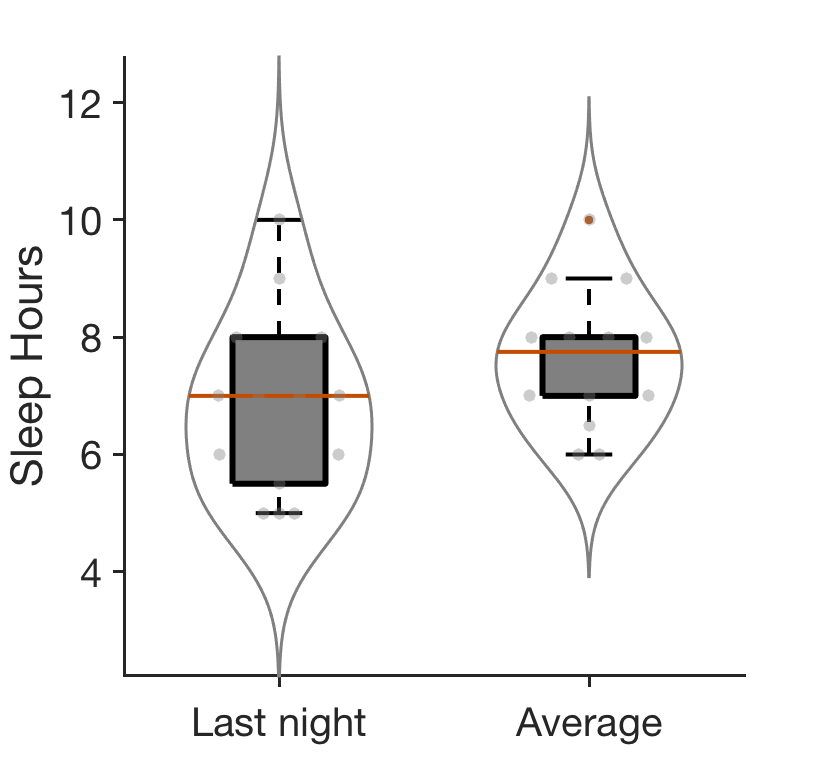

boxplot_wani_2016([sleep_hours_last_night' sleep_average'], 'violin', 'dots');
xticklabels({'Last night', 'Average'});
ylabel('Sleep Hours');
set(gca, 'fontsize', 20);
set(gcf, 'position', [1   965   411   380]);